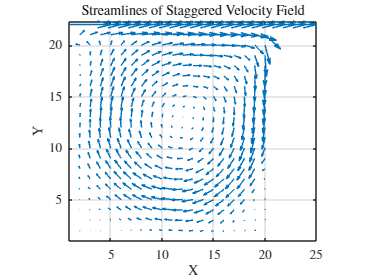


clear all;
set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
% Load the staggered velocity components

% uCurrent = csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\PostProcessing\uCurrent_MATLAB_Re100_64_CDS.csv')';
% vCurrent = csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\PostProcessing\vCurrent_MATLAB_Re100_64_CDS.csv')';
% PressureField = csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\PostProcessing\PressureField_Re100_64_CDS.csv')';

uCurrent = csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\uCurrent_MATLAB_Re1000_64_UDS.csv')';
vCurrent = csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\vCurrent_MATLAB_Re1000_64_UDS.csv')';
PressureField = csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\PressureField_Re1000_64_UDS.csv')';



% Define grid dimensions
[Nx_u, My_u] = size(uCurrent);
[Nx_v, My_v] = size(vCurrent);
[Nx_p, My_P] = size(PressureField);

% Create meshgrid for plotting
[X_u, Y_u] = meshgrid(1:My_u, 1:Nx_u);
[X_v, Y_v] = meshgrid(1:My_v, 1:Nx_v);
[X_p, Y_p] = meshgrid(linspace(0,1,Nx_u), linspace(0,1,My_v));
% Interpolate vCurrent to the uCurrent grid
[X_v_interp, Y_v_interp] = meshgrid(linspace(1, My_v, My_u), linspace(1, Nx_v, Nx_u));
vCurrent_interp = interp2(X_v, Y_v, vCurrent, X_v_interp, Y_v_interp);

% Plot streamlines
figure;
quiver(X_u, Y_u, uCurrent, vCurrent_interp, 'AutoScale', 'on', 'AutoScaleFactor', 3);
xlabel('X');
ylabel('Y');
title('Streamlines of Staggered Velocity Field');
axis tight;
axis equal;
grid on;

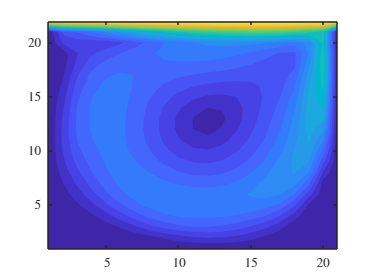

figure;
contourf(X_u, Y_u, sqrt(uCurrent.^2 + vCurrent_interp.^2), 20, 'LineColor', 'none');

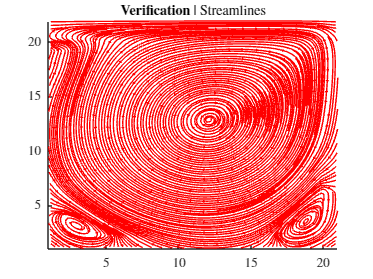

figure;
l=streamslice(X_u, Y_u, uCurrent, vCurrent_interp, 10, 'arrows', 'linear'); 
axis tight
% xlim([0 Nx_u]); ylim([0 My_u]);
set(l,'LineWidth',0.1)
set(l,'Color','r');
title("$\textbf{Verification}$ | Streamlines")

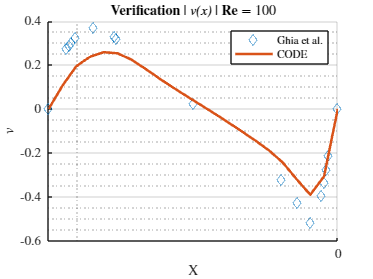

% Data
x_over_L = [0, 0.0625, 0.0703, 0.0781, 0.0938, 0.1563, 0.2266, 0.2344, 0.5, 0.8047, 0.8594, 0.9063, 0.9453, 0.9531, 0.9609, 0.9688, 1];
v_Re100 = [0, 0.09233, 0.10091, 0.1089, 0.12317, 0.16077, 0.17507, 0.17527, 0.05454, -0.24533, -0.22445, -0.16914, -0.10313, -0.08864, -0.07391, -0.05906, 0];
v_Re1000 = [0.00000, 0.27485, 0.29012, 0.30353, 0.32627, 0.37095, 0.33075, 0.32235, 0.02526, -0.31966, -0.42665, -0.51550, -0.39188, -0.33714, -0.27669, -0.21388, 0.00000];

% Plotting
% p = polyfit(x_over_L, v_Re100, 5); 
x_finer = linspace(0,1,My_v); 
% v_fitted = polyval(p, x_finer);
scatter(x_over_L, v_Re1000, 'Marker','diamond'); 
hold on;
vCurrent_Line = vCurrent(My_v / 2, :);
plot(x_finer, vCurrent(My_v / 2, :), 'LineWidth', 2); grid on;  grid minor; 
L = My_v; title('$\textbf{Verification}$ | $\textit{v(x)}$ |  $\textbf{Re} = 100$');
legend('Ghia et al.', 'CODE');
% Set custom tick marks
xticks([1, L/4, L/2, 3*L/4, L]); 
xlabel('X'); ylabel('$v$');
% Label the tick marks
xticklabels({'0', 'L/4', 'L/2', '3L/4', 'L'});

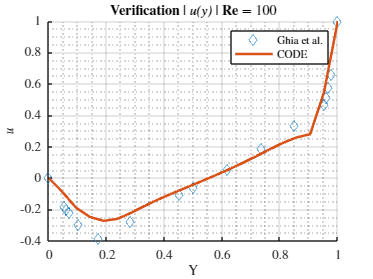

% Data
figure;
y_over_L = [1, 0.9766, 0.9688, 0.9609, 0.9531, 0.8516, 0.7344, 0.6172, 0.5, 0.4531, 0.2813, 0.1719, 0.1016, 0.0703, 0.0625, 0.0547, 0];
u_Re100 = [1, 0.84123, 0.78871, 0.73722, 0.68717, 0.23151, 0.00332, -0.13641, -0.20581, -0.2109, -0.15662, -0.1015, -0.06434, -0.04775, -0.04192, -0.03717, 0];
u_Re1000 = [1.00000, 0.65928, 0.57492, 0.51117, 0.46604, 0.33304, 0.18719, 0.05702, -0.06080, -0.10648, -0.27805, -0.38289, -0.29730, -0.22220, -0.20196, -0.18109, 0.00000];

scatter(y_over_L, u_Re1000, 'Marker','diamond'); 
hold on; 
y_finer = linspace(0,1,Nx_u); 
uCurrent_Line = uCurrent(:, ( My_u + 1 )/ 2)' ;
xlabel('Y'); ylabel('$u$');

plot(y_finer, uCurrent_Line, 'LineWidth', 2); grid on; grid minor; 
title('$\textbf{Verification}$ | $\textit{u(y)}$ |  $\textbf{Re} = 100$')
legend('Ghia et al.', 'CODE');
hold off;

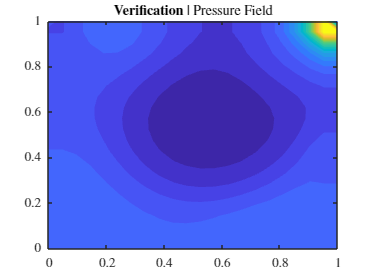

contourf(X_p, Y_p, PressureField, 20, 'LineColor', 'none');
title("$\textbf{Verification}$ | Pressure Field");

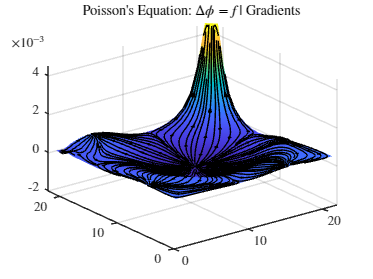

figure;
surf(PressureField); shading interp;
[u_Stream,v_Stream] = gradient(PressureField);
l = streamslice(u_Stream,v_Stream,2);
set(l,'Color','k');
for i=1:length(l)
    zi = interp2(PressureField,l(i).XData, l(i).YData);
    l(i).ZData = zi;
end
title("Poisson's Equation: $\Delta\phi = \textit {f}$ | Gradients ");

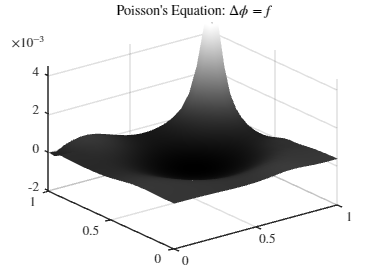

figure;
surf(X_p, Y_p, PressureField); shading interp; colormap("gray");
title("Poisson's Equation: $\Delta\phi = \textit {f} $");